# **Demo -- Optimization**

This demo shows the steps of the optimization for the project on:

**"Learning dynamical systems with bifurcations"**

clear all;
close all;

## Add dependencies and folders to path

addpath(genpath('.'));

## Load and prepare data

You can load data from a .csv file or from a .mat file:

disp('Choose a value for loading files.');

Choose a value for loading files.


disp('1     Loads file with time as first column (data_simulation, data_icub).')

1     Loads file with time as first column (data_simulation, data_icub).


disp('2     Loads file with time as last column (data_polishing).');

2     Loads file with time as last column (data_polishing).


disp('3     Loads files of kinesthetic data (data_LfD).')

3     Loads files of kinesthetic data (data_LfD).


ld = input('Your choice:\n');
if(ld == 1)
    % data files in 3D with 'time' as first column
    [data,time] = loadData([],4,1);     % leave it empty to select file at runtime
    len = 2500;
    st = 35;
    if size(data,1) >= len
        traj.data = data(st:len+st,:);
        traj.time = time(st:len+st,:);
    else
        traj.data = data(st:end,:);
        traj.time = time(st:end,:);
    end
    traj.size = size(traj.data,1);
elseif(ld == 2)
    % data files in 3D with 'time' as last column
    [data,time] = loadData([],4,0);     % leave it empty to select file at runtime
    traj.data = data(1000:4000,:);
    traj.time = time(1000:4000,:);
    traj.size = size(traj.data,1);
elseif(ld == 3)
    % data for Learning from Demonstration
    load('circular_wiping_dataset.mat');
    j = input('Select trajectory number, 1 or 3 (defaults to 1):\n');
    if j~=1 && j~=3
        j = 1;
    end
    X = proc_data{j}.X(1:3,any(True_states{j}==[1,2],2))';
    X = X(1:end-50,:);
    time = proc_data{j}.dt;
    type = 4;
    smoothing = 30;
    T = [];
else    % Loads some toy data instead
    load('circle_rho2_M3_Rm1_th0_th0_th0.mat');
end

Now we prepare the data and convert it to spherical coordinates:

if (exist('Xstored','var'))
    type = 1;
    X = Xstored;
    time = [];
    smoothing = 0;
    T = 1000;
elseif (exist('trial','var'))
    type = 2;
    X = [trial.position_real.x, trial.position_real.y, trial.position_real.z];
    time = trial.position_real.time;
    smoothing = 10;
    T = [];
elseif (exist('traj','var'))
    type = 3;
    X = traj.data;
    smoothing = 30;
    time = traj.time;
    if (isfield(traj,'size'))
        T = traj.size;
    else
        T = [];
    end
end
[Xdata,Xvel,Rdata,Rvel,dt,T,N,m,begin] = prepareData(type,X,time,smoothing,T);

## Plot data

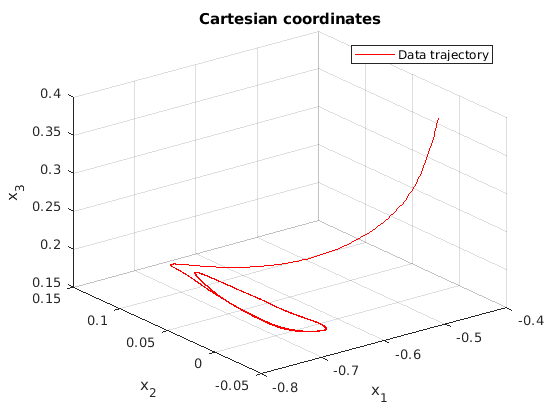

plotData(Xdata,Xvel,Rdata,Rvel,T,m,'cartp');
legend('Data trajectory','Location','northeast');

## Find $\omega$ limit set

Initialize and perform Expectation Maximization on a Gaussian Mixture Model with 1 or 2 Gaussians to find the model of the limit set:

j = input('Choose number of Gaussian models (defaults to 1):\n');
if j~=1 && j~=2
    j = 1
end
[Priors, Mu, Sigma] = EM_init_kmeans([Xdata';Xvel'], j);
[Priors, Mu, Sigma] = EM([Xdata';Xvel'], Priors, Mu, Sigma);

Plot the cluster found as the $\omega$ limit set:

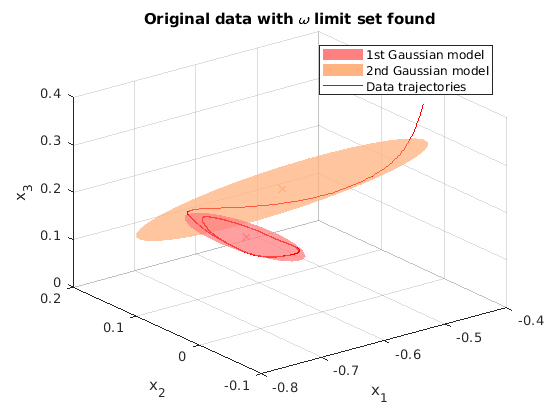

figure; grid on; hold on; view(3);
title('Original data with \omega limit set found');
xlabel('x_1'); ylabel('x_2'); zlabel('x_3');
if j == 2
    plotGMM(Mu(1:3,1), Sigma(1:3,1:3,1), [1 0.5 0.5], 4);
    plotGMM(Mu(1:3,2), Sigma(1:3,1:3,2), [1 0.7 0.5], 4);
    plot3(Xdata(:,1), Xdata(:,2), Xdata(:,3), 'r');
    legend('1st Gaussian model','2nd Gaussian model','Data trajectories','Location','northeast');
else
    plotGMM(Mu(1:3,:), Sigma(1:3,1:3,:), [1 0.5 0.5], 4);
    plot3(Xdata(:,1), Xdata(:,2), Xdata(:,3), 'r');
    legend('Gaussian model','Data trajectories','Location','northeast');
end

## If wanted, perfom dimensionality reduction

Decide if you want to perform dimensionality reduction:

prompt = 'Enter 1 to perform dimensionality reduction and 0 to skip it:\n';
dimred = input(prompt);

If wanted, perform dimensionality reduction (PCA) and plot projected data:

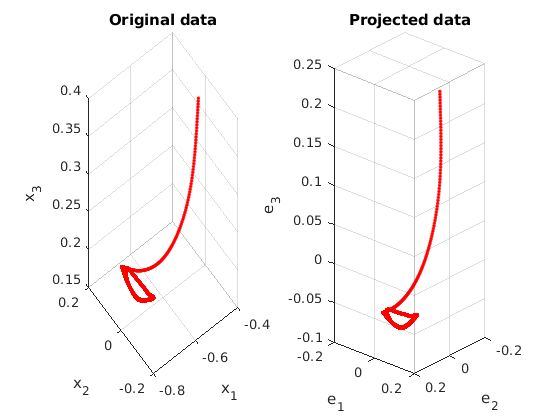

if (j == 2)     % if there are more clusters, choose which one to perform eigenvalue decomposition on
    prompt = 'Choose which gaussian to keep (1 for 1st, 2 for 2nd):\n';
    k = input(prompt);
else
    k = 1;
end
if (dimred == 1)
    % Get rotation matrix from PCA performed on covariance matrix of gaussian:
    [Rrot,~] = eig(Sigma(1:N,1:N,k));
    Rrot = Rrot(:,N:-1:1);
    
    % Plot projected (rotated) data
    if true
        figure; hold on; grid on;
        subplot(1,2,1); hold on; grid on;
        title('Original data'); xlabel('x_1'); ylabel('x_2'); zlabel('x_3');
        subplot(1,2,2); hold on; grid on;
        title('Projected data'); xlabel('e_1'); ylabel('e_2'); zlabel('e_3');
        
        for i = 1:sum(T)
            Xplot = (Rrot \ (Xdata(i,:)' - Mu(1:N,1)))';
            if N == 2
                subplot(1,2,1); plot(Xdata(i,1), Xdata(i,2), 'r.'); grid on; hold on;
                subplot(1,2,2); plot(Xplot(1), Xplot(2), 'r.'); grid on; hold on;
            else
                subplot(1,2,1); view(3); plot3(Xdata(i,1), Xdata(i,2), Xdata(i,3), 'r.'); grid on; hold on;
                subplot(1,2,2); view(3); plot3(Xplot(1), Xplot(2), Xplot(3), 'r.'); grid on; hold on;
            end
        end
    end
else
    % If you are not performing dimensionality reduction
    Rrot = eye(N);
end


% Find Euler angle (or rotation angle if N = 2)
if(N == 3)
    theta0 = rotm2eul(Rrot)
elseif(N == 2)
    theta0 = acos(Rrot(1,1))
end

theta0 =    -1.5227    0.0573    0.3030



% Get rotated data and save original data
Xdata_ = Xdata;
Xdata = (Rrot \ (Xdata' - Mu(1:N,k)))';

## Optimization

Select initial values of paramaters and optimize:

initial_parameters = [];
% Set initial rho0 to variance of Gaussian model
initial_parameters.rho0 = 3*mean(diag(Sigma(1:N,1:N,1)));
% If you want to exclude x0 from optimization, use x0 = []
initial_parameters.x0 = [];
% If you want to exclude M from the second opt, use M = []
% initial_parameters.M = [];
[params] = optimizePars(initial_parameters,Xdata,dt,begin,1);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>


<a href = "matlab

err1 = 0.8159

err2 = 80.5309

Parameters found by optimization:


params = struct with fields:
    rho0: 0.0581
       M: 1.4892
       R: -1.0622
       a: [1 1.1607 1.4547]
      x0: [0 0 0]


## Get parameters learned

rho0 = params.rho0;
M = params.M;
R = params.R;
% Rewrite a to include rotation matrix
a = Rrot; for i = 1:N; a(i,i) = a(i,i) / params.a(i); end
% Add the mean of the Gaussian model to x0
if isfield(initial_parameters,'x0') && isempty(initial_parameters.x0)
    x0 = -Mu(1:N,1)';
else
    x0 = (Rrot * params.x0' - Mu(1:N,1))';
end
params.x0 = x0;
params.theta0 = theta0;
params.Rrot = Rrot;
disp(params);

      rho0: 0.0581
         M: 1.4892
         R: -1.0622
         a: [1 1.1607 1.4547]
        x0: [0.5797 -0.0828 -0.1996]
    theta0: [-1.5227 0.0573 0.3030]
      Rrot: [3×3 double]



## Functions to plot learned dynamics

dU = @(r,M,rho0,R) 2.*M.*(r(:,1) - rho0);
dRho = @(r,M,rho0,R) - sqrt(M.*2) .* (r - rho0);
dTheta = @(r,M,rho0,R) R .* exp(-dU(r(:,1),M,rho0,R).^2);

r = @(Xplot) cart2hyper((a\(Xplot+x0)')');
if N == 3
    dr = @(r) [dRho(r(:,1),M,rho0,R), dRho(r(:,2),M,0,R), dTheta(r(:,1),M,rho0,R)];
else
    dr = @(r) [dRho(r(:,1),M,rho0,R), dTheta(r(:,1),M,rho0,R)];
end
y = @(Xplot) sph2cartvelocities(r(Xplot),dr(r(Xplot))); % dynamics to be plotted

## Plot learned dynamics with original data and new trajectories

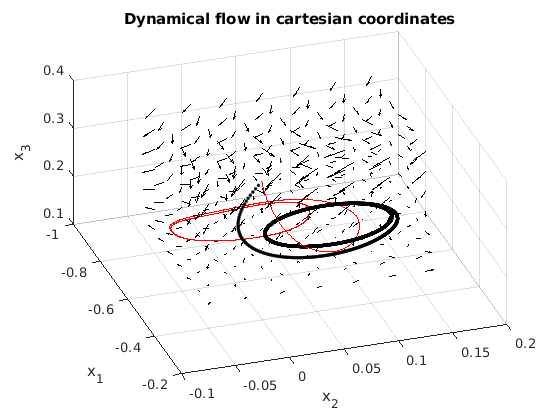

% Get unrotated data
Xdata = Xdata_;

% Plot original data
figure; title('Dynamical flow in cartesian coordinates'); hold on; grid on;
if N == 2
    plot(Xdata(:,1),Xdata(:,2),'r.'); hold on;
else
    view(3);
    plot3(Xdata(1:T(1),1),Xdata(1:T(1),2),Xdata(1:T(1),3),'r'); hold on;
    for i = 2:m
        plot3(Xdata(sum(T(1:i-1))+1:sum(T(1:i)),1),...
            Xdata(sum(T(1:i-1))+1:sum(T(1:i)),2),...
            Xdata(sum(T(1:i-1))+1:sum(T(1:i)),3),'r'); hold on;
    end
end

% Plot streamlines / arrows to show dynamics
ylabel('x_2'); yl = ylim;
xlabel('x_1'); xl = xlim;
if N > 2
    zlabel('x_3'); zl = zlim;
    ngrid = 7;
end

if N == 2
    [Xs,Ys] = meshgrid(linspace(xl(1),xl(2),20),linspace(yl(1),yl(2),20));
    X_plot = [Xs(:), Ys(:)];
else
    [Xs,Ys,Zs] = meshgrid(linspace(xl(1),xl(2),ngrid),...
        linspace(yl(1),yl(2),ngrid),linspace(zl(1),zl(2),ngrid));
    X_plot = [Xs(:), Ys(:), Zs(:)];
end
Y = zeros(size(X_plot));
for i= 1:size(X_plot,1)
    Y(i,1:N) = y(X_plot(i,1:N));
end

if N == 2
    streamslice(Xs,Ys,reshape(Y(:,1),20,20),...
        reshape(Y(:,2),20,20),'method','cubic');
else
    quiver3(X_plot(:,1),X_plot(:,2),X_plot(:,3),Y(:,1),Y(:,2),Y(:,3),'color','black');
end

% Test dynamics for T time steps
X0 = Xdata(1,:);
Xvel_DS = []; Rad_s = []; X_s = []; Rad_vel = [];
for j = 1:size(X0,1)
    X = X0(j,:);
    for i = 1:T(1)
        Rad = r(X) + dr(r(X)) * dt;
        Rad_s = [Rad_s; Rad];
        Rad_vel = [Rad_vel; dr(r(X))];
        X = (a*hyper2cart(Rad)')' - x0;
        X_s = [X_s; X];
        Xvel_DS = [Xvel_DS; sph2cartvelocities(r(X),dr(r(X)))];
        if N == 2
            plot(X(1),X(2),'k.'); hold on; grid on;
        else
            plot3(X(1),X(2),X(3),'k.'); hold on; grid on;
        end
    end
end

## Evaluation

normalized = 1;
rmserr = RMSErr(Xdata,Xvel,params,Rrot,dt,normalized);
disp('RMSE (normalized):');

RMSE (normalized):


disp(rmserr);

    0.3825




coserr = cosSim(Xdata,Xvel,params,Rrot,dt);
disp('Cosine similarity:');

Cosine similarity:


disp(coserr);

    0.4577




% Error for full reproduction:
rmserr_DS = 1/(T) * sum(vecnorm((Xvel - Xvel_DS),2,2))./ max(max(Xvel) - min(Xvel));
disp('RMSE for DS full (normalized):');

RMSE for DS full (normalized):


disp(rmserr_DS);

    0.4490



for i=2:T; err(i-1)=(Xvel_DS(i,:) * Xvel(i,:)') / (norm(Xvel(i,:))*norm(Xvel_DS(i,:))); end
coserr_DS = 1/(T) * sum(abs(1 - err));
disp('Cosine similarity for DS full:');

Cosine similarity for DS full:


disp(coserr_DS);

    0.9260





% Save values if needed (optional -- uncomment)
%save("eval.mat",'rmserr','coserr');

## Testing reproduction with DMP learning (optional -- uncomment)

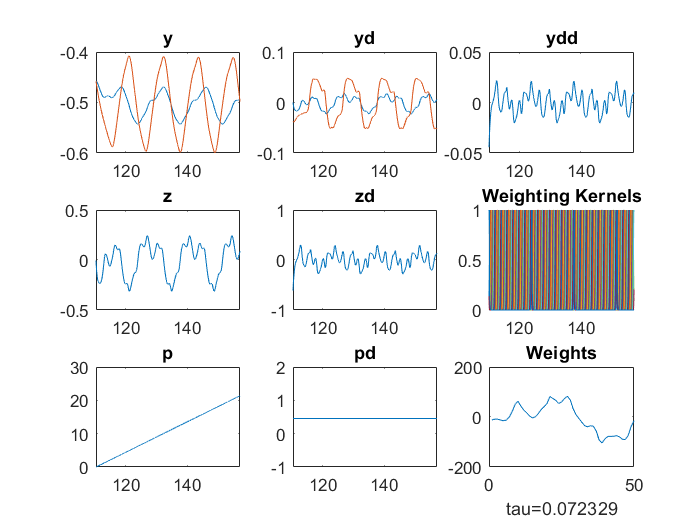

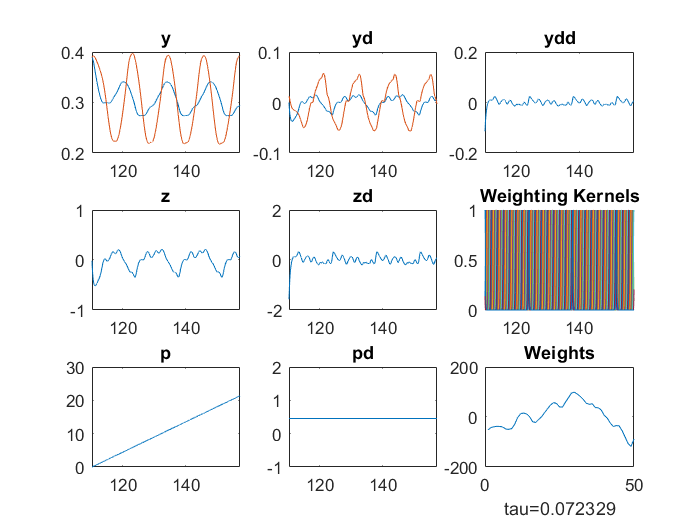

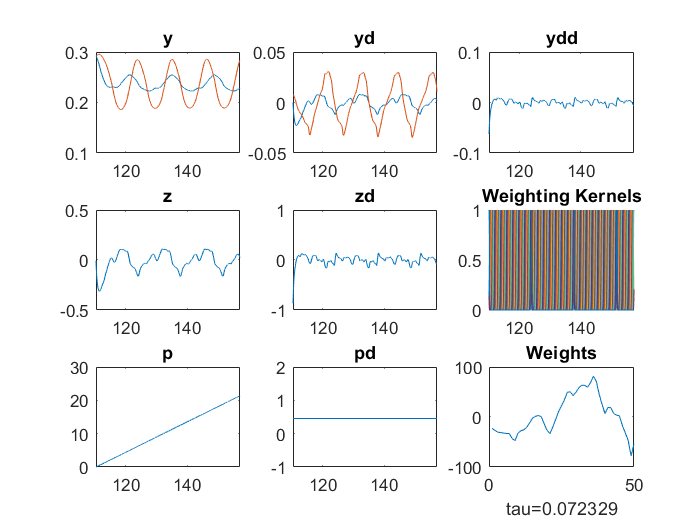

% st = 301;
% global rcps;
% XvelSm = [smooth(Xvel(st:end,1),20), smooth(Xvel(st:end,2),20), smooth(Xvel(st:end,3),20)];
% if length(time) == T+1
%     time = time(1:end-1);
% elseif length(time) == 1
%     time = [dt:dt:T*dt]';
% end
% [XDMP,XvDMP] = LearningDMPComparison(Xdata(st:end,:),XvelSm,dt,time(st:end,:),0);

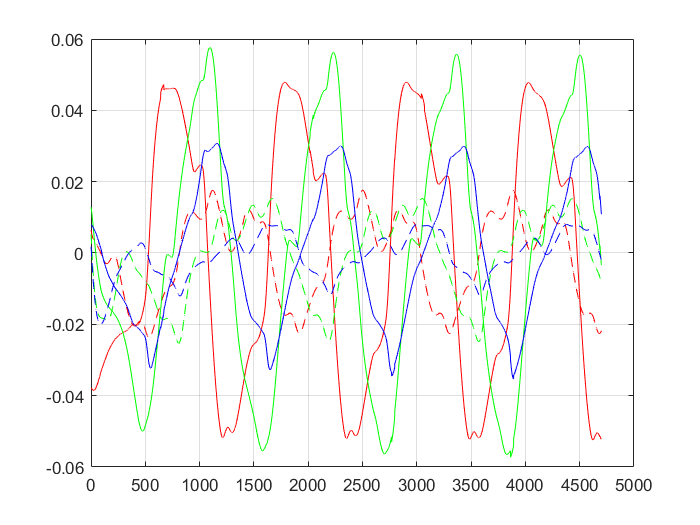

% % figure; plot(Xdata(st:end,:)); hold on; grid on; plot(XDMP,'--');
% % title('Original data and reproduced data with DMP');
% % 
% % rmserr_DMP = 1/(T-st+1) * sum(vecnorm((Xvel(st:end,:) - XvDMP),2,2))./ max(max(Xvel(st:end,:)) - min(Xvel(st:end,:)));
% % disp('RMSE for DMP (normalized):');
% % disp(rmserr_DMP);
% % for i=2:T-st+1; err(i-1)=(XvDMP(i,:) * Xvel(i+st-1,:)') / (norm(Xvel(i+st-1,:))*norm(XvDMP(i,:))); end
% % coserr_DMP = 1/(T-st+1) * sum(abs(1 - err));
% % disp('Cosine similarity for DMP:');
% % disp(coserr_DMP);
% 
% Xvel_DMP = zeros(T-st+1,N);
% for ID = 1:N
%     rcp('change',ID,'y',Xdata(st,ID));
%     rcp('change',ID,'yd',Xvel(st,ID));
%     for i=1:T-st+1
%         [y,yd,ydd]=rcp('run',ID,rcps(ID).tau,dt);
%         P(i+1,:)   = [rcps(ID).p rcps(ID).pd];
%         Z(i+1,:)   = [rcps(ID).z rcps(ID).zd];
%         Y(i+1,:)   = [y yd ydd];
%         PSI(i+1,:) = rcps(ID).psi';
%         W(i+1,:,:) = rcps(ID).w;
%         Xvel_DMP(i,ID) = yd;
%     end
% end
% figure; title('Velocity original (-) vs learned with DMP (--)');
% for c=1:N
%     col = zeros(1,3);
%     col(c) = 1;
%     plot(Xvel(st:end,c),'Color',col); hold on; grid on; plot(Xvel_DMP(:,c),'LineStyle','--','Color',col);
% end

% 
% rmserr_DMP = 1/(T-st+1) * sum(vecnorm((Xvel(st:end,:) - Xvel_DMP),2,2))./ max(max(Xvel(st:end,:)) - min(Xvel(st:end,:)));
% disp('RMSE for DMP (normalized):');

RMSE for DMP (normalized):


% disp(rmserr_DMP);

    0.4983



% for i=2:T-st+1; err(i-1)=(Xvel_DMP(i,:) * Xvel(i+st-1,:)') / (norm(Xvel(i+st-1,:))*norm(Xvel_DMP(i,:))); end
% coserr_DMP = 1/(T-st+1) * sum(abs(1 - err));
% disp('Cosine similarity for DMP:');

Cosine similarity for DMP:


% disp(coserr_DMP);

    1.2900



## Export parameters to .mat file

% save("params.mat",'params');

## Export parameters to .txt file (optional -- uncomment)

% saveToTxt(params);

## Export parameters to ROS configuration file (optional -- uncomment)

% saveToCfg(params);